# Image Analysis for Biometric features

Identify points in a frame that correspond the center point of a fish's head by analyzing the intensity characteristics of the larvae. The solution should not depend on threshold values that are manually determined. Investigate the accuracy of your determinations.

## Acquiring images from file

clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
imtool close all;  % Close all imtool figures.
clear;  % Erase all existing variables.
workspace;  % Make sure the workspace panel is showing.

grayfishds = imageDatastore("zebraFish\frames_grey", "FileExtensions",".png", "LabelSource","foldernames");
numImgs = length(grayfishds.Labels);

numFish = 8;
numProcessed = 0;
totalFishFound = 0;

for i = 1:1
    img = readimage(grayfishds, 149);
end

## Convert Image to Grayscale

Despite the image already being in grayscale, matlab still considers the image an rgb even though the rgb values are all the same within each pixel. Converting the to grayscale gets rid of the rgb and allows the usage of functions that require grayscale images.

    grayimg = im2gray(img);

## Edge Detection

Using edge detection to see if it helps separate the fish from the background.

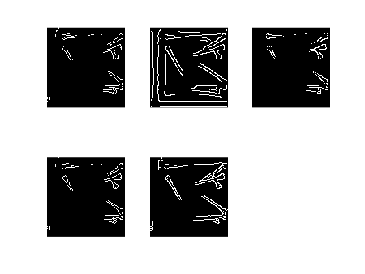

    edges_prewitt = edge(grayimg,"prewitt");
    edges_canny = edge(grayimg,"canny");
    edges_roberts = edge(grayimg,"roberts");
    edges_sobel = edge(grayimg,"sobel");
    edges_approxcan = edge(grayimg,"approxcanny");

    figure;
    subplot(2,3,1);
    imshow(edges_prewitt);
    subplot(2,3,2);
    imshow(edges_canny);
    subplot(2,3,3);
    imshow(edges_roberts);
    subplot(2,3,4);
    imshow(edges_sobel);
    subplot(2,3,5);
    imshow(edges_approxcan);
    linkaxes;


% sensitivity = .72
% lower = .35
% sensitivity = .5
% lower = .31
    sensitivity = 0.75

sensitivity = 0.7500

    lower = 0.29

lower = 0.2900

    sigma = 0.49

sigma = 0.4900

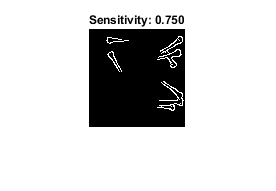

% ,
    edges_canny = edge(grayimg, "canny",[lower,sensitivity],sigma);
    figure;
    test = imshow(edges_canny);
    title(sprintf("Sensitivity: %.03f", sensitivity));

    

    BW3 = uint8(edges_canny*255);
    edge_gray = grayimg+BW3;
    
    

## Multithresh and Image segmentation

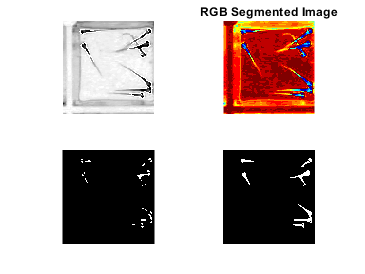

    figure;
    subplot(2,2,1)
    imshow(edge_gray);
    thresh = multithresh(edge_gray, 15);
    seg_I = imquantize(edge_gray,thresh);
    RGB = label2rgb(seg_I);
    threshedimg= im2gray(RGB);
    subplot(2,2,2)
    imshow(RGB);
    axis off
    title('RGB Segmented Image');
    eyesregions = (seg_I == 1 );
   
    subplot(2,2,3)
    imshow(eyesregions);
    
    headregions = ( seg_I == 1 | seg_I == 2 | seg_I == 3 | seg_I == 4 | seg_I == 5 | seg_I == 6 | seg_I == 7 );
    headregions = bwareaopen(headregions, 10);
    subplot(2,2,4)
    imshow(headregions)
    linkaxes;

## Labeling segments using 8 connectivity

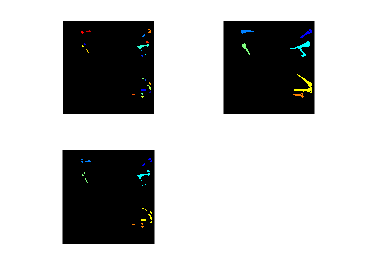

    
    eyesObjects = bwconncomp(eyesregions);
    headObjects = bwconncomp(headregions);
    

    labeledEyes = labelmatrix(eyesObjects);
    labeledHeads = labelmatrix(headObjects);

    figure;
    subplot(2,2,1);
    imshow(label2rgb(labeledEyes,'jet','k','shuffle'));
    subplot(2,2,2);
    imshow(label2rgb(labeledHeads,'jet','k','shuffle'));
    
    numeyes = eyesObjects.NumObjects;
    numbodies = headObjects.NumObjects;

    for i = 1:numeyes
        for n = 1:numbodies
            if all(ismember(eyesObjects.PixelIdxList{i},headObjects.PixelIdxList{n}))
                labeledEyes(eyesObjects.PixelIdxList{i}) = n;
                break;
            elseif n == numbodies
                labeledEyes(eyesObjects.PixelIdxList{i}) = 0;
            end
        end
    end

    subplot(2,2,3);
    imshow(label2rgb(labeledEyes,'jet','k','shuffle'));
    linkaxes;

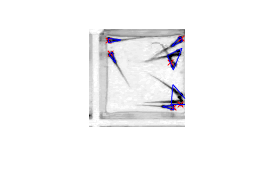

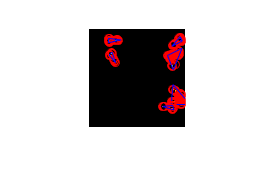

    
    markHeads = figure;
    triangleFig = figure;

    figure(triangleFig);
    imshow(label2rgb(labeledEyes,'jet','k','shuffle'));
    hold on;

    [a,~,~] = unique(reshape(labeledEyes',[],1),'stable');
    numbodies = size(a)-1;

    figure(markHeads);
    imshow(grayimg);
    hold on;
    for i = 1:numbodies
        smallestTriSide = Inf;
        smallTriPoint1 = 0;
        smallTriPoint2 = 0;
        [row,col] = find(labeledEyes == a(i+1));
        [trix,triy]= minboundtri(row, col);
        figure(triangleFig);
        plot(col,row,'ro',triy,trix,'b-');

        for n = 1:size(trix)-1
            p1 = [trix(n);triy(n)];
            p2 = [trix(n+1);triy(n+1)];
            distance = abs(norm(p1 - p2));
            if distance < smallestTriSide
                smallestTriSide = distance;
                smallTriPoint1 = [trix(n),triy(n)];
                smallTriPoint2 = [trix(n+1),triy(n+1)];
            end
        end

        out = (smallTriPoint1(:) + smallTriPoint2(:)).'/2;
        figure(markHeads);
        plot(out(2),out(1),'rx',triy,trix,'b-');

    end

## Bounding Box Triangle Function

function [trix,triy] = minboundtri(x,y)
% minboundtri: Compute the minimum area bounding triangle of points in the plane
% usage: [trix,triy] = minboundtri(x,y)
%
% arguments: (input)
%  x,y - vectors of points, describing points in the plane as
%        (x,y) pairs. x and y must be the same size.
%
%
% arguments: (output)
%  trix,triy - 4x1 vectors of points that define the minimum
%        area bounding triangle.
%
%
% Example usage:
%  x = randn(50,1);
%  y = randn(50,1);
%  [tx,ty] = minboundtri(x,y);
%  plot(x,y,'ro',tx,ty,'b-')
%
%
% See also: minboundcircle, minboundrect
%
%
% Author: John D'Errico
% E-mail: woodchips@rochester.rr.com
% Release: 1.0
% Release date: 3/14/07
% preprocess data
x=x(:);
y=y(:);
% not many error checks to worry about
n = length(x);
if n~=length(y)
  error 'x and y must be the same sizes'
end
% start out with the convex hull of the points to
% reduce the problem dramatically. Note that any
% points in the interior of the convex hull are
% never needed, so we drop them.
xy = [x,y];
if n>3
  edges = convhulln(xy);
  
  % exclude those points inside the hull as not relevant
  % also sorts the points into their convex hull as a
  % closed polygon
  [junk,I,J] = unique(edges(:));
  xy = xy(edges(I),:);
  edges = reshape(J,size(edges));
  
elseif n==3
  % its a triangle already
  edges = [1 2;2 3;3 1];
elseif n==2
  % its a single edge
  trix = xy([1 2 1 1],1);
  triy = xy([1 2 1 1],2);
  return
elseif n==1
  % its a single point
  trix = xy([1 1 1 1],1);
  triy = xy([1 1 1 1],2);
  return
else
  % empty begets empty
  trix = [];
  triy = [];
  return
end
nedges = size(edges,1);
% now we must find the bounding triangle of those
% that remain.
% special case small numbers of points. If we trip any
% of these cases, then we are done, so return.
if nedges == 3
  trix = xy([1 2 3 1],1);
  triy = xy([1 2 3 1],2);
  return
end
% more than 3 points.
% get the angle of each edge of the hull polygon.
edgeangles = atan2(xy(edges(:,2),2) - xy(edges(:,1),2), ...
  xy(edges(:,2),1) - xy(edges(:,1),1));
edgelen = sqrt((xy(edges(:,2),2) - xy(edges(:,1),2)).^2 + ...
  (xy(edges(:,2),1) - xy(edges(:,1),1)).^2);
[edgelen,tags] = sort(edgelen,1,'descend');
edges = edges(tags,:);
edgeangles = edgeangles(tags);
% Will need a 2x2 rotation matrix through an angle theta
Rmat = @(theta) [cos(theta) sin(theta);-sin(theta) cos(theta)];
% Loop over each edge of the hull - I'll contend that the minimum
% area triangle will contain at least one edge of the convex hull.
% In fact, often the triangle will contain up to 6 points from the
% convex hull - i.e., 3 edges.
area = inf;
nxy = size(xy,1);
opts = optimset('fminsearch');
opts.MaxFunEvals = 600;
opts.Display = 'none';
for i = 1:nedges
  % rotate the data through (pi/2 - theta)
  rot = Rmat(pi/2 - edgeangles(i));
  % around the center of the i'th edge
  xy0 = (xy(edges(i,1),:) + xy(edges(i,2),:))/2;
  xyt = (xy - repmat(xy0,nxy,1))*rot;
  if (max(xyt(:,1))/(max(xyt(:,1)) - min(xyt(:,1)))) > 1e-13
    % swap the edge orientation
    rot = Rmat(-pi/2 - edgeangles(i));
    xyt = -xyt;
  end
  
  % find the point which minimizes the triangle area
  minxt = min(xyt(:,1));
  xy3 = [.5*minxt,mean(xyt(:,2))];
  
  [xy3,A_i] = fminsearch(@trifun,xy3,opts);
  
  % new metric value for the current interval. Is it better?
  if A_i<area
    % keep this one
    [area,tpoly] = trifun(xy3);
    
    tpoly = tpoly*rot' + repmat(xy0,4,1);
  end
end
trix = tpoly(:,1);
triy = tpoly(:,2);
% all done
% =================================
% nested function
  function [area,txy] = trifun(xy3)
    % 
    xy3(1) = -abs(xy3(1)) + minxt*1.000001;
    
    slopes = (xyt(:,2) - xy3(2))./(xyt(:,1) - xy3(1));
    yint = xy3(2) - slopes*xy3(1);
    y2 = max(yint);
    y1 = min(yint);
    
    % negative of the triangle area
    area = -xy3(1)*(y2-y1)/2;
    
    txy = [0 y1;0 y2;xy3;0 y1];
    
  end % trifun
% =================================
end % mainline end